1. e 2. Crie uma estrutura de dados (por exemplo, uma tabela) e guarde as seguintes informações relativas a cada áudio: a. diretório do áudio; b. nome do ficheiro (com extensão); c. participante; d. dígito; e. número da repetição. Desenvolva código para importação dos sinais de áudio e guarde o valor da taxa de amostragem e os sinais na estrutura de dados criada.

pastaAudios = '33';  
audios = dir(fullfile(pastaAudios, '*.wav'));

tabelaDados = table('Size', [0 7], ...
    'VariableTypes', {'string','string','string','double','double','double','double'}, ...
    'VariableNames', {'diretorio','nomeFicheiro','participante','digito','repeticao','sinal','taxaAmostragem'});

for i = 1:length(audios)
    nomeFicheiro = audios(i).name;
    diretorio = fullfile(pastaAudios, nomeFicheiro);
    
    partesNome = split(nomeFicheiro, '_'); 
    
    digito = str2double(partesNome{1});      
    participante = partesNome{2};  
    
    partesRepeticao = split(partesNome{3}, '.');  
    repeticao = str2double(partesRepeticao{1});
    
    [sinal, taxaAmostragem] = audioread(diretorio);

    novaEntrada = {diretorio, nomeFicheiro, participante, digito, repeticao, sinal, taxaAmostragem};
    tabelaDados = [tabelaDados; novaEntrada];
end

disp(tabelaDados);

       diretorio        nomeFicheiro     participante    digito    repeticao         sinal          taxaAmostragem
    ________________    _____________    ____________    ______    _________    ________________    ______________

    "33\0_33_0.wav"     "0_33_0.wav"         "33"          0           0        {33565×1 double}        48000     
    "33\0_33_1.wav"     "0_33_1.wav"         "33"          0           1        {26896×1 double}        48000     
    "33\0_33_10.wav"    "0_33_10.wav"        "33"          0          10        {33524×1 double}        48000     
    "33\0_33_11.wav"    "0_33_11.wav"        "33"          0          11        {32539×1 double}        48000     
    "33\0_33_12.wav"    "0_33_12.wav"        "33"          0          1

3. Reproduza e represente graficamente um exemplo dos sinais importados, identificando o dígito e o número da repetição a que cada um corresponde, e indicando o eixo horizontal com o tempo em segundos.

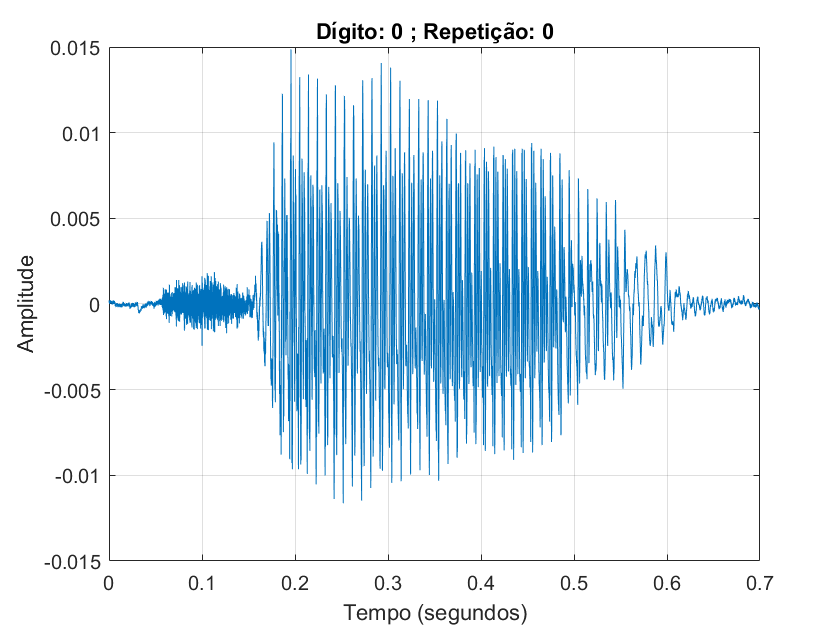

i = input('Linha: '); 

audio = tabelaDados(i, :);
digito = audio.digito;  
repeticao = audio.repeticao;  
sinal = audio.sinal{1};  
taxaAmostragem = audio.taxaAmostragem;  

tempo = (0:length(sinal)-1) / taxaAmostragem;

plot(tempo, sinal);
xlabel('Tempo (segundos)');
ylabel('Amplitude');
title(['Dígito: ', num2str(digito), ' ; Repetição: ', num2str(repeticao)]), grid on;

4. Uma estratégia que pode melhorar a diferenciação entre dígitos é fazer uma etapa de préprocessamento para garantir que todos os ficheiros têm a mesma duração e intervalo de amplitude. Para isso deverá implementar os seguintes passos: 

-Retirar o “silêncio” inicial dos sinais, de forma a garantir que todos começam exatamente ao mesmo tempo (por exemplo, através do estudo da Energia do sinal ao longo do tempo).

 -Normalizar a amplitude com base na amplitude máxima e mínima das amostras. Isto garante que os problemas usuais da gravação do som (por exemplo, a distância da pessoa ao microfone) não interferem na análise. 

-Adicionar (ou retirar) silêncio no fim dos ficheiros para garantir que todos têm a mesma duração total. Guarde os sinais após o pré-processamento na estrutura de dados criada no ponto 1.

amplitudeMinima=0.0025

amplitudeMinima = 0.0025

tamanhoAudio=48000

tamanhoAudio = 48000

indiceInicio = find(abs(sinal) > amplitudeMinima, 1, 'first');
sinal = sinal(indiceInicio:end);

numColunas=tamanhoAudio-length(sinal)

numColunas = 22293

tabelaZeros = zeros(numColunas, 1);
sinal = [sinal;tabelaZeros]

sinal =     0.0026
    0.0027
    0.0027
    0.0028
    0.0029
    0.0030
    0.0031
    0.0031
    0.0030
    0.0031


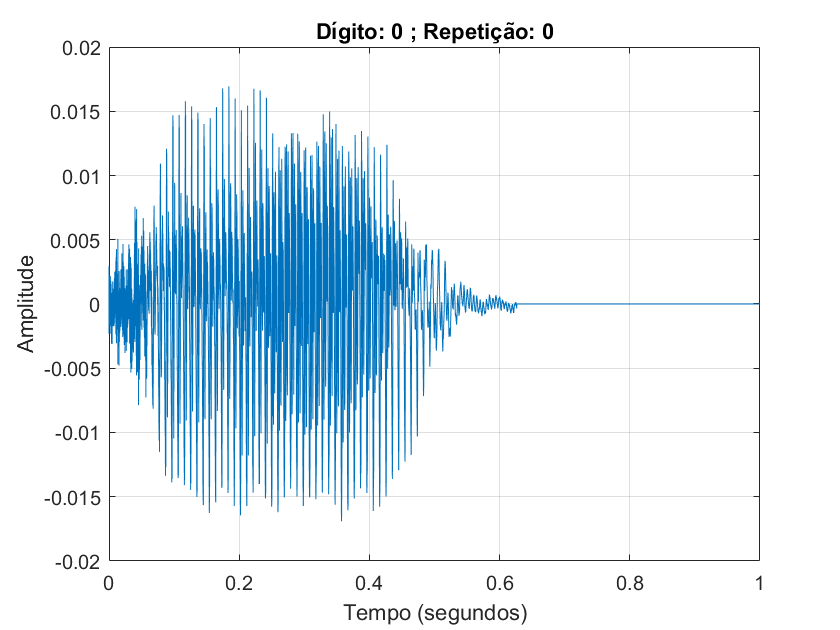

sinal = sinal / max(abs(sinal));

tempo2 = (0:length(sinal)-1) / taxaAmostragem;


plot(tempo2, sinalSemSilencio);
xlabel('Tempo (segundos)');
ylabel('Amplitude');
title(['Dígito: ', num2str(digito), ' ; Repetição: ', num2str(repeticao)]), grid on;